%_________________Data Generation_____________________
% This file provides a code for generating a random
% message that is transmitted through a RayTracing 
% channel with additive white gaussian noise between
% the transmitter and the reciever. The modulation 
% schemes can be edited to fit more classes, however,
% this code limits it to two types with varying order.
%_____________________________________________________

%Just to make sure everything runs smoothly close all.
close all
clc
clear all
%In case some figures are still open from previous run.

rng(2023) %Fix the random seed to get the same data.

%Please review the table attached to understand the 
%process of choosing the following parameters.
m_types = ["BPSK" "QPSK" "16QAM" "64QAM" '256QAM'];
M = [2, 4, 16, 64, 256];
SNR_limits = {[2 5] [5 11] [11 18] [18 29] [29 34]};
p0 = 0.5; %Probability of bit 0

%Location of our transmitter:
tx_lat = 22.282385;
tx_long = 114.165929;
alice = txsite( ...
    "Latitude",tx_lat, ...
    "Longitude",tx_long, ...
    "AntennaAngle",30, ...        % Azimuth angle
    "AntennaHeight",60, ...
    "TransmitterFrequency", 5e9, ... %5 MHz
    "TransmitterPower",2.5e-3);


%Our channel (Assume line of sight scenario)
pm = propagationModel("raytracing", ...
    "Method","image", ...
    "MaxNumReflections",0);

%Generating the Dataset
n_examples = 20000;
Dataset = zeros(256, 2, n_examples*length(m_types));
offset = [0 20000 40000 60000 80000];
latitude_range = linspace(22.282385, 22.292889, n_examples);
longitude_range = linspace(114.165929, 114.16571, n_examples);
for i = 1:length(m_types)
    L = 1024*log2(M(i)); %length of the message
    SNR = linspace(SNR_limits{i}(1), SNR_limits{i}(2), n_examples);
    for j = 1:n_examples
        data = rand(L, 1);
        data = int8(data > p0); %Random bits 0 with probability 0, and 1 with probability (1-p0) 
        if contains(m_types(i), "PSK")
            txSig =  pskmod(data, M(i), 0, "gray", "InputType","bit");
        else
            txSig =  qammod(data, M(i), "gray", "InputType","bit");
        end
        rxSig = awgn(txSig, SNR(j));
        new = [real(rxSig) imag(rxSig)];
        Dataset(:, :, j+offset(i)) = new(1:256, :);
        if (mod(j, 4000) == 0)
            disp(j)
        end
    end
    disp(i);
end

        4000

        8000

       12000

       16000

       20000



     1



        4000

        8000

       12000

       16000

       20000



     2



        4000

        8000

       12000

       16000

       20000



     3



        4000

        8000

       12000

       16000

       20000



     4



        4000

        8000

       12000

       16000

       20000



     5



SNR_array = linspace(SNR_limits{1}(1), SNR_limits{length(SNR_limits)}(2), n_examples*length(m_types));

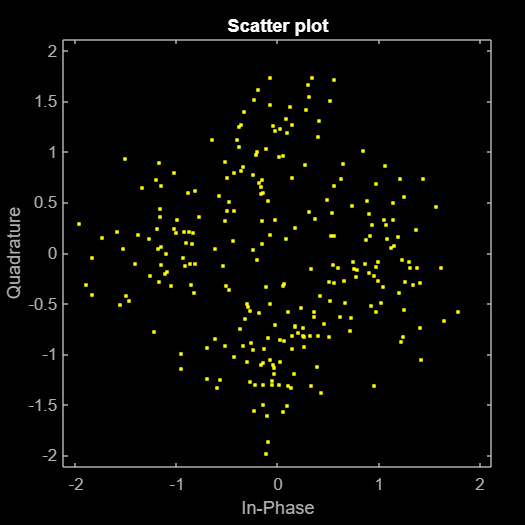

a = 20020;
Signal = Dataset(:, :, a);
scatterplot(Signal)